data = load('GSLData.csv');
years = data(:, 1);
temperatures = data(:, 2);
saltair = data(:, 3);
saline = data(:, 4);

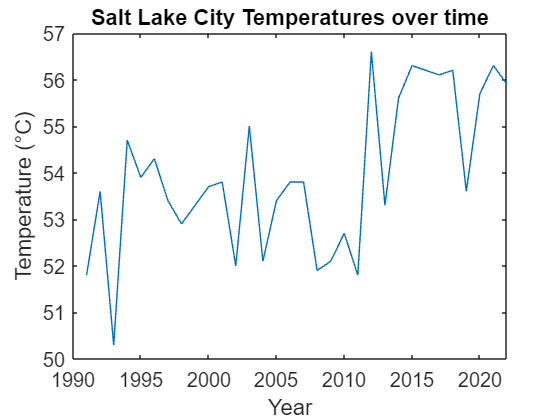

figure();
plot(years, temperatures);
title('Salt Lake City Temperatures over time')
xlabel('Year');
ylabel('Temperature (°C)');

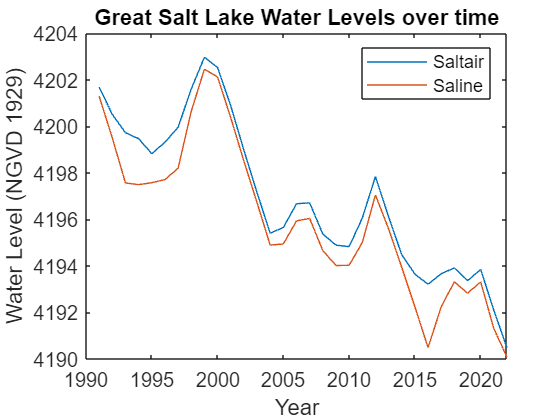

figure();
plot(years, saltair);
hold on;
plot(years, saline);
title('Great Salt Lake Water Levels over time')
xlabel('Year');
ylabel('Water Level (NGVD 1929)');
legend('Saltair', 'Saline')
hold off;

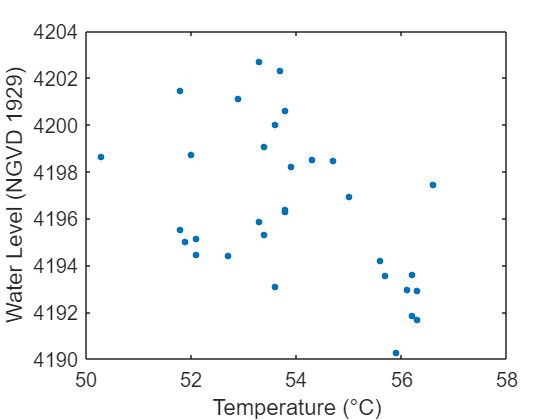

waterLevels = (saltair+saline)/2;
figure();
plot(temperatures, waterLevels, '.', 'LineStyle', 'none', 'MarkerSize', 10);
xlabel('Temperature (°C)');
title('The effect of temperature on the water levels in the Great Salt Lake');
ylabel('Water Level (NGVD 1929)');
hold on;
% Fit a linear trendline to the data
[m, b] = polyfit(temperatures, waterLevels, 1);
% Evaluate the trendline at the data points
tw_trend = polyval(m, temperatures);
plot(temperatures, tw_trend, '-');

CCSaltair = corrcoef(temperatures, saltair)

CCSaltair =     1.0000   -0.4685
   -0.4685    1.0000


CCSaline = corrcoef(temperatures, saline)

CCSaline =     1.0000   -0.4760
   -0.4760    1.0000
